# 21960197 向平 Assignment 6

# Ex 5.1.1

Make a table of the error of the three-point centered-difference formula for $f^{\prime } \left(0\right)$, where$f\left(x\right)=\sin \;x-\cos \;x$, with $h={10}^{-1} ,\ldotp \ldotp \ldotp ,{10}^{-12}$ , as in the table in Section 5.1.2. Draw a plot of the results. Does the minimum error correspond to the theoretical expectation?

f = @(x)sin(x)-cos(x);
f_prime =@(h)(f(h)-f(-h))./(2*h);
f_correct =@(x)cos(x)+sin(x);
correct_ans = f_correct(0);
h = ones(12,1);
for i=1:12
    h(i) = h(i)/(10^i);
end
error = (correct_ans-f_prime(h));
format shortE;
table(h,f_prime(h),error,'VariableNames',{'h','Three_point_centered_difference_formula','error'})

ans = 12×3 table
        h         Three_point_centered_difference_formula       error   
    __________    _______________________________________    ___________

    1.0000e-01                  9.9833e-01                    1.6658e-03
    1.0000e-02                  9.9998e-01                    1.6667e-05
    1.0000e-03                  1.0000e+00                    1.6667e-07
    1.0000e-04                  1.0000e+00                    1.6671e-09
    1.0000e-05                  1.0000e+00                    1.5653e-11
    1.0000e-06                  1.0000e+00                    2.6755e-11
    1.0000e-07                  1.0000e+00                    5.2636e-10
    1.0000e-08                  1.0000e+00                    5.2636e-10
    1.0000e-09                  1.0000e+00                   -2.7229e-08
    1.0000e-10                  1.0000e+00                   -8.2740e-08
    1.0000e-11                  1.0000e+00                   -8.2740e-08
    1.0000e-12                  1

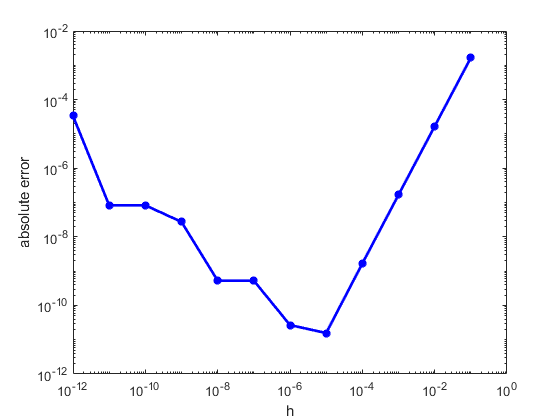

loglog(h,abs(error),'b-*','LineWidth',2);hold on;
xlabel('h');
ylabel('absolute error');

**From the above table and plot, we can observe that the minimum absolute error occurs about at **$h={10}^{-5}$. **In double precision, the theoretical smallest error occurs at **$h=\left(3 \epsilon_{\mathrm{mach}} / M\right)^{1 / 3}
$$\approx {10}^{-5}$, **which is consistent with the table and plot results.**

# Ex 5.2.1

Use the composite Trapezoid Rule and Simpson's Rule with m = 16 and 32 panels to approximate the definite integral. Compare with the correct integral and report the two errors.


$$\text { (a) } \int_{0}^{4} \frac{x d x}{\sqrt{x^{2}+9}}$$


% composite Trapezoid rule
% m = 16
m = 16;
h = 4/m;
x = 0:h:4;
y = @(x)x./sqrt(x.^2+9);
format long;
int_result = h/2*(y(x(1))+y(x(m+1))+2*sum(y(x(2:m))))

int_result =    1.998638181470279


int_correct = integral(y,0,4)

int_correct =    2.000000000000000


error = abs(int_result-int_correct)

error =    0.001361818529722


% m = 32
m = 32;
h = 4/m;
x = 0:h:4;
% y = @(x)x./sqrt(x.^2+9);
int_result = h/2*(y(x(1))+y(x(m+1))+2*sum(y(x(2:m))))

int_result =    1.999659678077911


error = abs(int_result-int_correct)

error =      3.403219220892151e-04


% Composite Simpson's rule
% m = 16
m = 16;
h = 4/(2*m);
x = 0:h:4;
% y = @(x)x./sqrt(x.^2+9);
int_result = h/3*(y(x(1))+y(x(end))+4*sum(y(x(2:2:2*m)))+2*sum(y(x(3:2:2*m-1))))

int_result =    2.000000176947122


error = abs(int_result-int_correct)

error =      1.769471218437957e-07


% m = 32
m = 32;
h = 4/(2*m);
x = 0:h:4;
int_result = h/3*(y(x(1))+y(x(end))+4*sum(y(x(2:2:2*m)))+2*sum(y(x(3:2:2*m-1))))

int_result =    2.000000011037514


error = abs(int_result-int_correct)

error =      1.103751356978933e-08



$$\text { (c) } \int_{0}^{1} x e^{x} d x$$


% composite Trapezoid rule
% m = 16
m = 16;
h = 1/m;
x = 0:h:1;
y = @(x)x.*exp(x);
format long;
int_result = h/2*(y(x(1))+y(x(m+1))+2*sum(y(x(2:m))))

int_result =    1.001444027067708


int_correct = integral(y,0,1)

int_correct =      1


error = abs(int_result-int_correct)

error =    0.001444027067708


% m = 32
m = 32;
h = 1/m;
x = 0:h:1;
int_result = h/2*(y(x(1))+y(x(m+1))+2*sum(y(x(2:m))))

int_result =    1.000361038046700


error = abs(int_result-int_correct)

error =      3.610380466998464e-04


% Composite Simpson's rule
% m = 16
m = 16;
h = 1/(2*m);
x = 0:h:1;
int_result = h/3*(y(x(1))+y(x(end))+4*sum(y(x(2:2:2*m)))+2*sum(y(x(3:2:2*m-1))))

int_result =    1.000000041706364


error = abs(int_result-int_correct)

error =      4.170636414002615e-08


% m = 32
m = 32;
h = 1/(2*m);
x = 0:h:1;
int_result = h/3*(y(x(1))+y(x(end))+4*sum(y(x(2:2:2*m)))+2*sum(y(x(3:2:2*m-1))))

int_result =    1.000000002606974


error = abs(int_result-int_correct)

error =      2.606973970031845e-09


# Ex 5.2.7

Apply the Composite Midpoint Rule to the following improper integrals with$\;m=16\;\textrm{and}\;32$.


$$\text { (c) } \int_{0}^{1} \frac{\arctan x}{x} d x$$


% Composite Midpoint Rule
% m = 16
m = 16;
h = 1/m;
x = 0+h/2:h:1-h/2;
y = @(x) atan(x)./x;
int_result = h*sum(y(x(:)))

int_result =    0.916012051029311


int_correct = integral(y,0,1)

int_correct =    0.915965594177219


error = abs(int_result-int_correct)

error =      4.645685209170303e-05


% m = 32
m = 32;
h = 1/m;
x = 0+h/2:h:1-h/2;
int_result = h*sum(y(x(:)))

int_result =    0.915977207391470


error = abs(int_result-int_correct)

error =      1.161321425058315e-05


From the above resuts, we can observe that when the $m$ increases, the calculation precision increases.

# Ex 5.5.3

Approximate the integrals in Exercise 1, using n = 4 Gaussian Quadrature, and give the error.


$$\left(a\right)\int_{-1}^1 \left(x^3 +2x\right)d\;x$$


**Solution:**

roots $x_i$: $x_1 =-\sqrt{\frac{15+2\sqrt{30}}{35}},x_2 =-\sqrt{\frac{15-2\sqrt{30}}{35}}\;,x_3 =\sqrt{\frac{15-2\sqrt{30}}{35}},x_4 =\sqrt{\frac{15+2\sqrt{30}}{35}}$

coefficients $c_i :$


$$c_1 =\frac{90-5\sqrt{30}}{180},c_2 =\frac{90+5\sqrt{30}}{180}\;,c_3 =\frac{90+5\sqrt{30}}{180},c_4 =\frac{90-5\sqrt{30}}{180}$$


The $n=2$Gaussian Quadrature approximation is


$$\int_{-1}^1 \left(x^3 +2x\right)d\;x\approx c_1 f\left(x_1 \right)+c_2 f\left(x_2 \right)+c_3 f\left(x_3 \right)+c_4 f\left(x_4 \right)$$


                            
$$\approx$$


f = @(x)x.^3 + 2*x;
x = zeros(4,1);
x(1) = -1*sqrt((15+2*sqrt(30))/35);
x(2) = -1*sqrt((15-2*sqrt(30))/35);
x(3) = sqrt((15-2*sqrt(30))/35);
x(4) = sqrt((15+2*sqrt(30))/35);
c = zeros(4,1);
c(1) = (90-5*sqrt(30))/180;
c(2) = (90+5*sqrt(30))/180;
c(3) = (90+5*sqrt(30))/180;
c(4) = (90-5*sqrt(30))/180;
format long;
int_gaussian = sum(c.*f(x))

int_gaussian =      0


int_correct = integral(f, -1, 1)

int_correct =      0


error = abs(int_gaussian-int_correct)

error =      0
